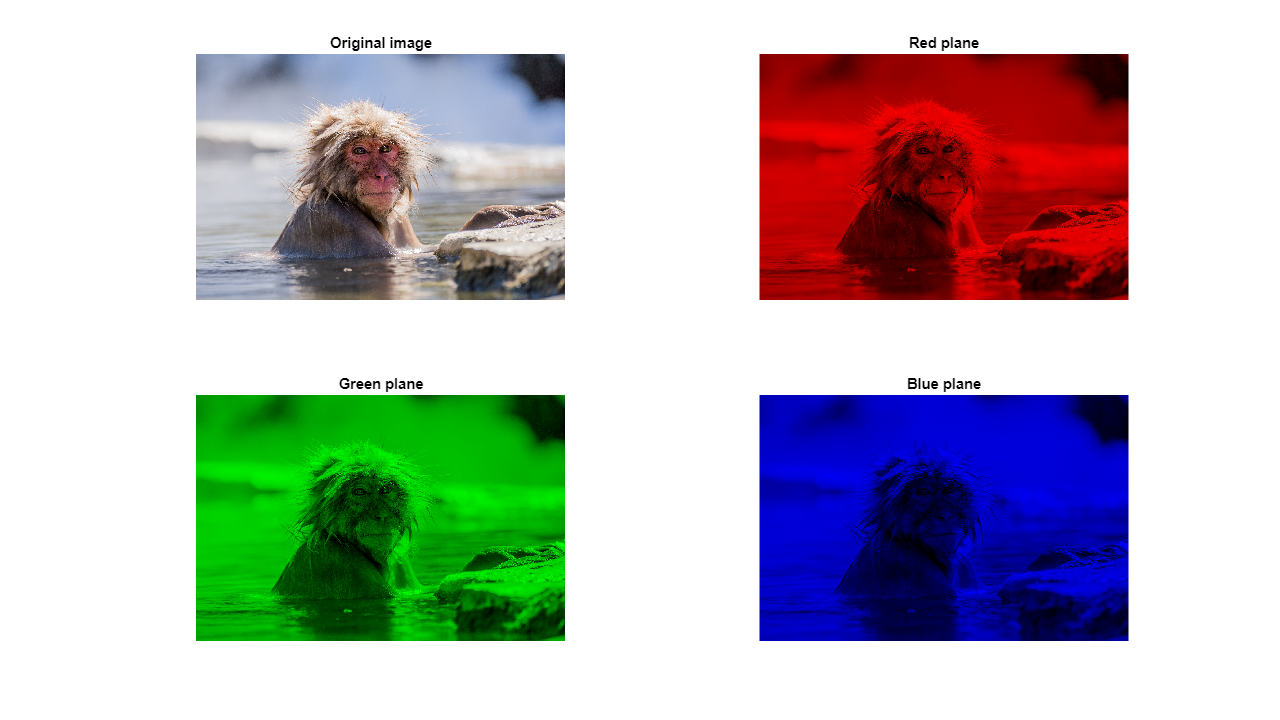

 
[fname, fpath] = uigetfile( ...
    {'*.jpg;*.jpeg;*.png'}, ...
    'Select file to open' ...
);

im = imread([fpath, fname]);
[r, c, d] = size(im);

R = uint8(zeros(r, c, d));
G = uint8(zeros(r, c, d));
B = uint8(zeros(r, c, d));

R(:, :, 1) = im(:, :, 1);
G(:, :, 2) = im(:, :, 2);
B(:, :, 3) = im(:, :, 3);

f1 = figure(Name="RGB image components");
f1.Position = [0 0 1280 720];
axis off;

subplot(2, 2, 1);
imshow(im);
title('Original image');
subplot(2, 2, 2);
imshow(R);
title('Red plane');
subplot(2, 2, 3);
imshow(G);
title('Green plane');
subplot(2, 2, 4);
imshow(B);
title('Blue plane');

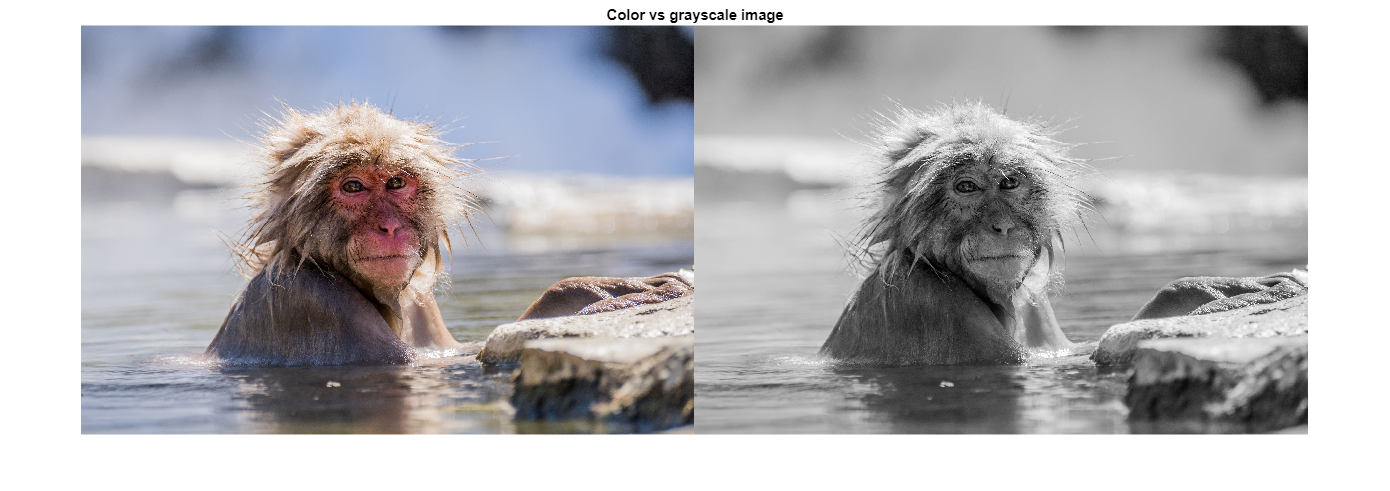


figure;
grayed = rgb2gray(im);
imshowpair(im, grayed, 'montage');
title("Color vs grayscale image")

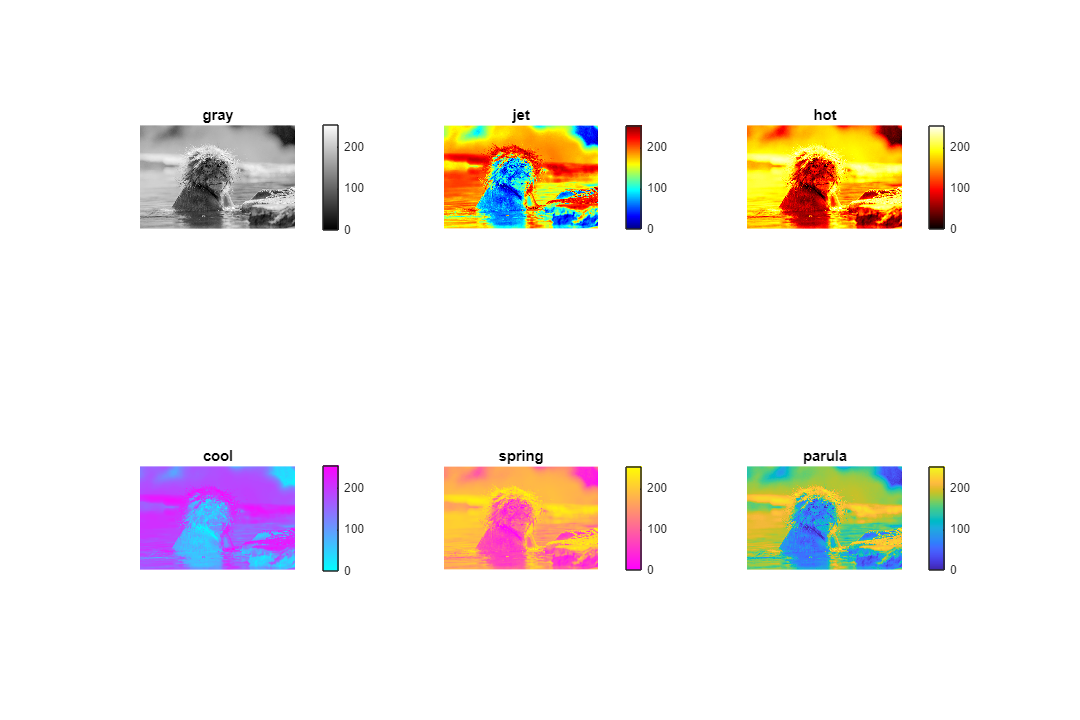


% rgb2hsv and hsv2rgb can be used for conversion
% between rgb to hsv and vice-versa

f2 = figure(Name="Colormaps on grayscale image");
f2.Position = [0 0 1080 720];
colormaps = ["gray" "jet" "hot" "cool" "spring" "parula"];
for i = 1 : length(colormaps)
    sp = subplot(2, 3, i);
    imshow(grayed);
    colormap(sp, colormaps(i));
    colorbar;
    title(colormaps(i));
end